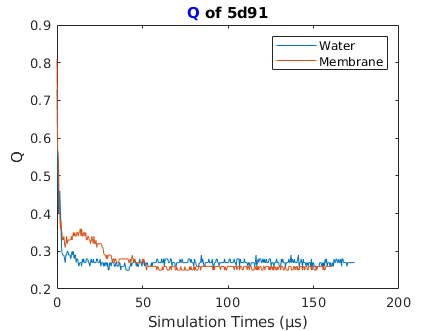

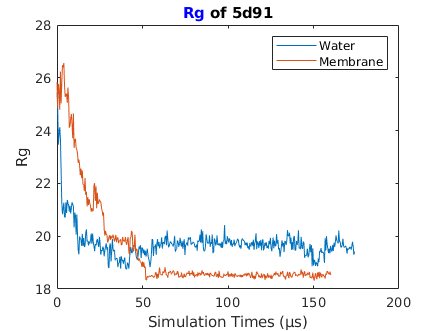

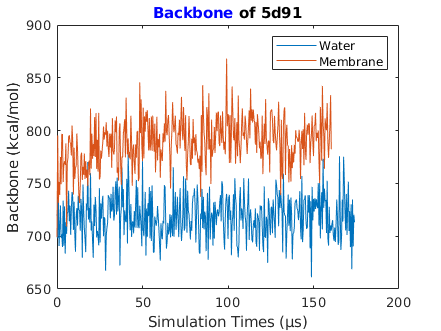

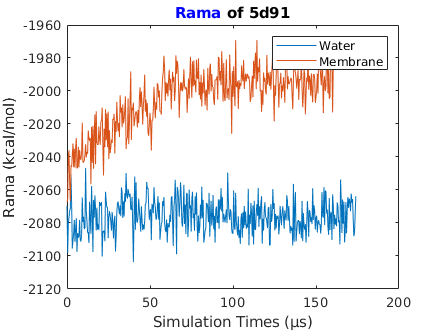

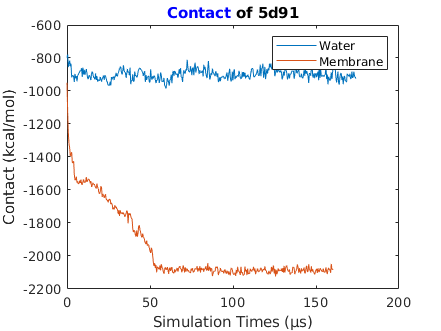

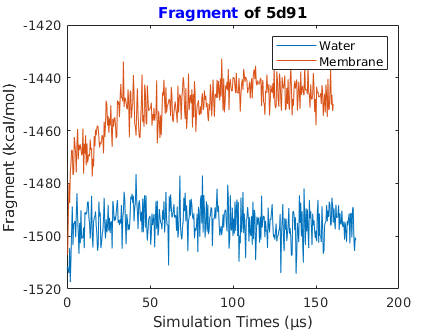

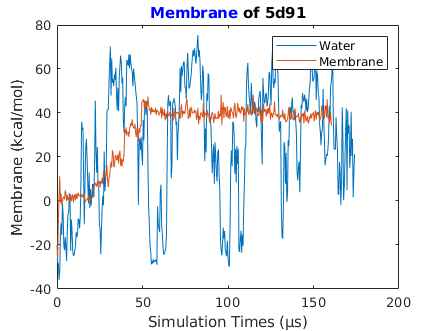

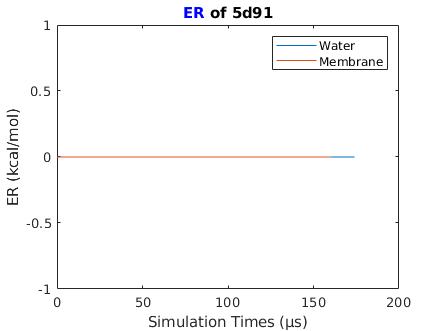

% Step 1: Read the .dat files
data_water = readmatrix('info_water1.dat');
data_membrane = readmatrix('info_mem1.dat');

steps_water = data_water(:,1) * 0.4; 
steps_membrane = data_membrane(:,1) * 0.4;

% Names of the columns for the sake of labels
names = {'Q', 'Rg', 'Backbone', 'Rama', 'Contact', 'Fragment', 'Membrane', 'ER', 'TBM_Q', 'Beta', 'Pap', 'Helical', 'Total'};

% Specify the folder to save the figures
outputFolder = 'Plot1';  % Change this to your desired output folder

% Step 2: Plot the data
for i = 2:size(data_water, 2)  % Starting from the second column as the first one is steps
    figure;  % Create a new figure for each plot
    
    % Plot data from water and membrane separately
    plot(steps_water, data_water(:,i), 'DisplayName', 'Water');
    hold on;
    plot(steps_membrane, data_membrane(:,i), 'DisplayName', 'Membrane');
    
    xlabel('Simulation Times (µs)');  % Add x-axis label
    
    % Add y-axis label
    if strcmp(names{i-1}, 'Q') || strcmp(names{i-1}, 'Rg')
        ylabel(names{i-1}); 
    else
        ylabel([names{i-1} ' (kcal/mol)']); 
    end
    
    % Add title with different colors
    ax = gca;  % Get handle to current axes
    ax.LabelFontSizeMultiplier = 1.1;  % Optional: Increase font size of labels relative to axes
    ax.Title.String = {['\color{blue}', names{i-1}, '\color{black}', ' of 5d91']};  % Add title
    ax.Title.Interpreter = 'tex';  % Set interpreter

    % Add legend
    legend;

    % Save the figure
    saveas(gcf, fullfile(outputFolder, [names{i-1} '_comparison.png']));
end